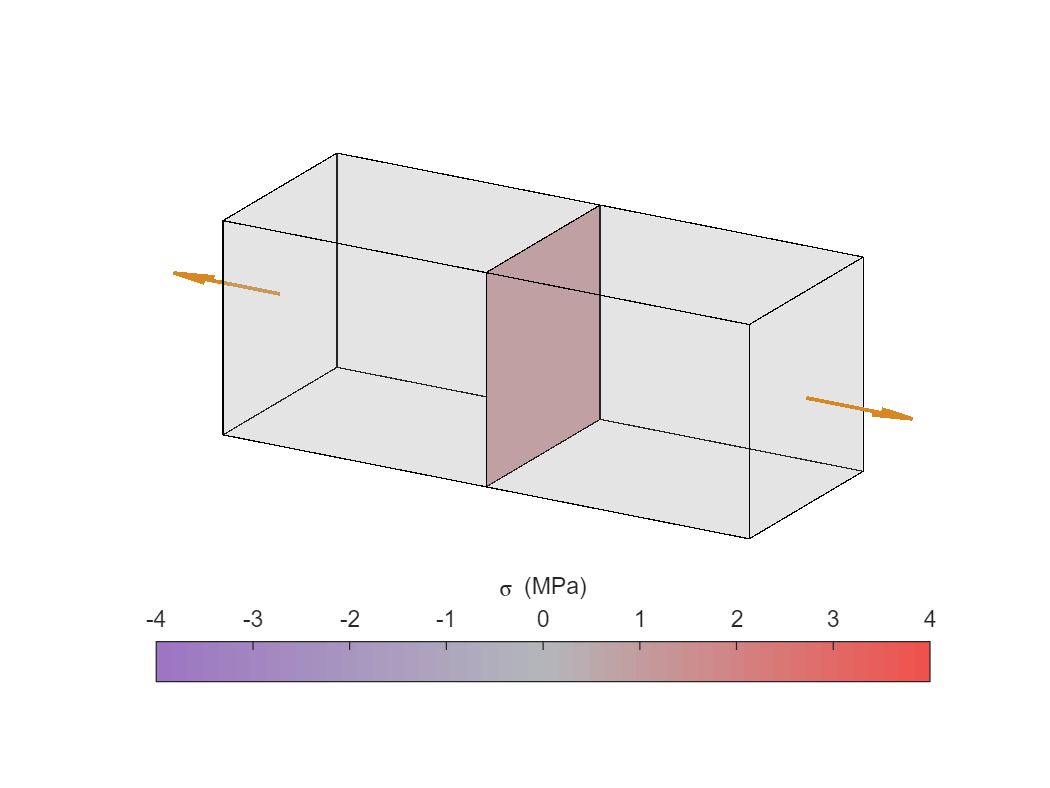

close all
    
F =500* 1e3; % Axial force (N)
w0 =0.75; % Width (m)
L0 = 2;   % Length (m)

visualizeAxialStress(F,L0,w0);

function visualizeAxialStress(F,L0,w0)
    
    % Calculations
    N = 50;
    sigmaL = F/(w0*w0); % In N/m^2 = Pa
    sigMax = 1000e3/0.5^2;
    sigIdx = round(N/2*sigmaL/abs(sigMax)) + N/2 + 1;
    sigIdx(sigIdx < 1) = 1;
    sigIdx(sigIdx > N) = N;
%     sigIdx = round(50*sign(sigmaL)*log(abs(sigmaL))/log(abs(sigMax)));
    purpleRed = purpleRedMap(N);
    planeColor = purpleRed(sigIdx ,:);
    

    % Visualization parameters
    cubeEdgeAlpha = 1;
    cubeAlpha = 0.2;
    cubeColors = [1 1 1]*0.7;
    forceColor = [215 136 37]/255;
    axLims = [-1 1 -2 2 -1.2 0.8]*0.6;
    Fscale = 0.8e-6;
    arrowheadScale = 0.4;
    Flw = 1.5;
    
    % Cube and deformations
    [vertices,faces,normals] = cubeValues();
    vertices = vertices - 0.5;
    vertices(:,2) = vertices(:,2)*L0;
    vertices(:,[1,3]) = vertices(:,[1,3])*w0;

    % Plane
    yp = [0 0 0 0 0];
    xp = w0/2*[-1 1 1 -1 -1];
    zp = w0/2*[-1 -1 1 1 -1];

    % Create plot
    patch("Vertices",vertices,"Faces",faces,"EdgeAlpha",cubeEdgeAlpha,...
        "FaceColor","Flat","FaceVertexCData",cubeColors,"FaceAlpha",cubeAlpha);
    patch("XData",xp,"YData",yp,"ZData",zp,"FaceColor",planeColor)
    hold on

    % Force vectors
    ymneg = mean(vertices([1 2 5 6],2));
    quiver3(0,ymneg,0,0,-F*Fscale,0,"Color",forceColor,"LineWidth",Flw,...
        "AutoScale","off","MaxHeadSize",arrowheadScale/abs(F*Fscale))
    ympos = mean(vertices([3 4 7 8],2));
    quiver3(0,ympos,0,0,F*Fscale,0,"Color",forceColor,"LineWidth",Flw,...
        "AutoScale","off","MaxHeadSize",arrowheadScale/abs(F*Fscale))

    % Axis settings
    hold off
    view(120,20)
    axis equal
    axis(axLims)
    set(gca,"Clipping","off")
    axis off
    colormap(purpleRed)
    cbar = colorbar("location","south");
    ylabel(cbar,"\sigma (MPa)")
    clim([-1 1]*sigMax/1e6)
end

function [vertices,faces,normals] = cubeValues()
    vertices = [0 0 0; 1 0 0; 1 1 0; 0 1 0;
                0 0 1; 1 0 1; 1 1 1; 0 1 1];
    faces = [1 2 3 4 1; 5 6 7 8 5; 1 2 6 5 1; 
             3 4 8 7 3; 1 4 8 5 1; 2 3 7 6 2];
    normals = [0 0 -1; 0 0 1; 0 -1 0; 0 1 0; -1 0 0; 1 0 0];
end

function purpleRed = purpleRedMap(N)
    % Creates a custom color map (red - black - green)
    baseColors = [121 91 150;...
                  138 140 144;...
                  184 63 59]*1.3/255;
    purpleRed = interp1([-1 0 1],baseColors,linspace(-1,1,N));
end